Consider first the function

f  = @(x) (x-1).*(x-2);

At the root $r=1$, we have $f'(r)=-1$. If the values of $f$ were perturbed at any point by noise of size, say, $0.05$, we can imagine finding the root of the function as though drawn with a thick line, whose edges we show here.

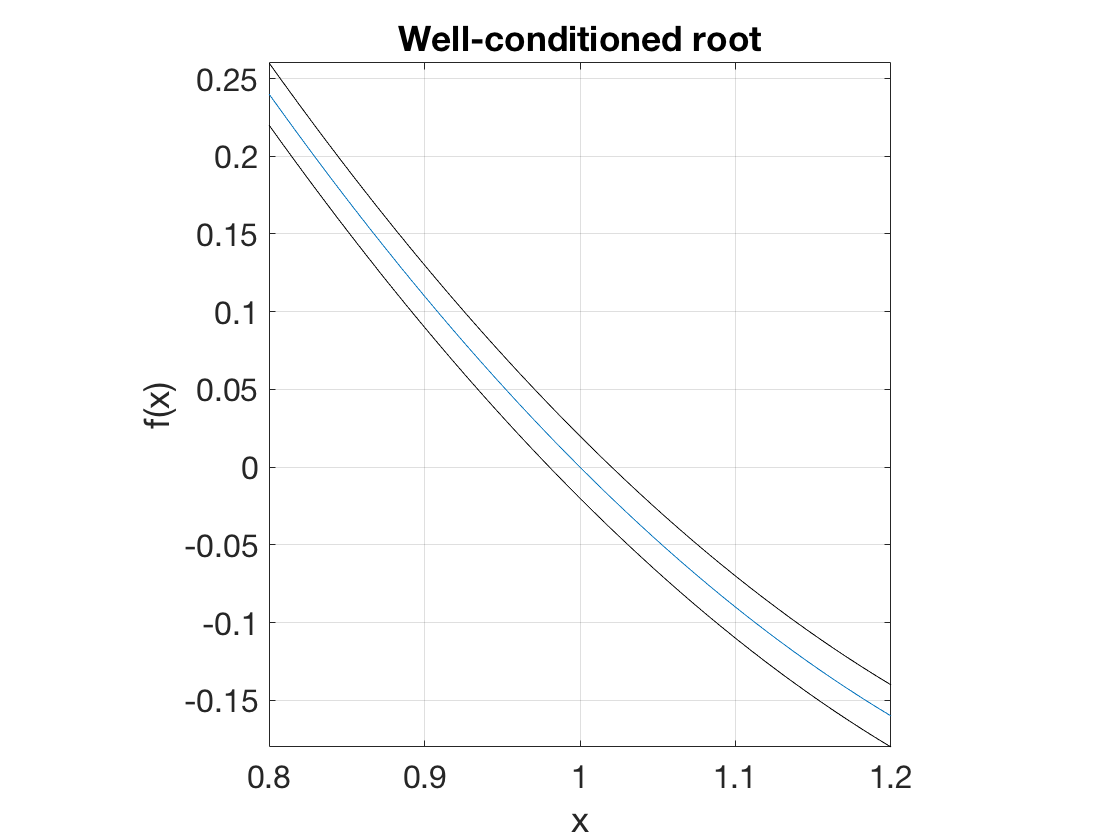

interval = [0.8 1.2];
fplot(f,interval), grid on, hold on
fplot(@(x) f(x)+0.02,interval,'k')
fplot(@(x) f(x)-0.02,interval,'k')
axis equal     % ignore this line
xlabel('x'), ylabel('f(x)')    % ignore this line
title('Well-conditioned root')    % ignore this line

The possible values for a perturbed root all lie within the interval where the black lines intersect the $x$ axis. The width of that zone is about the same as the vertical distance between the lines.

By contrast, consider the function

f  = @(x) (x-1).*(x-1.01);

Now $f'(1)=-0.01$, and the graph of $f$ will be much shallower near $x=1$. Look at the effect this has on our thick rendering:

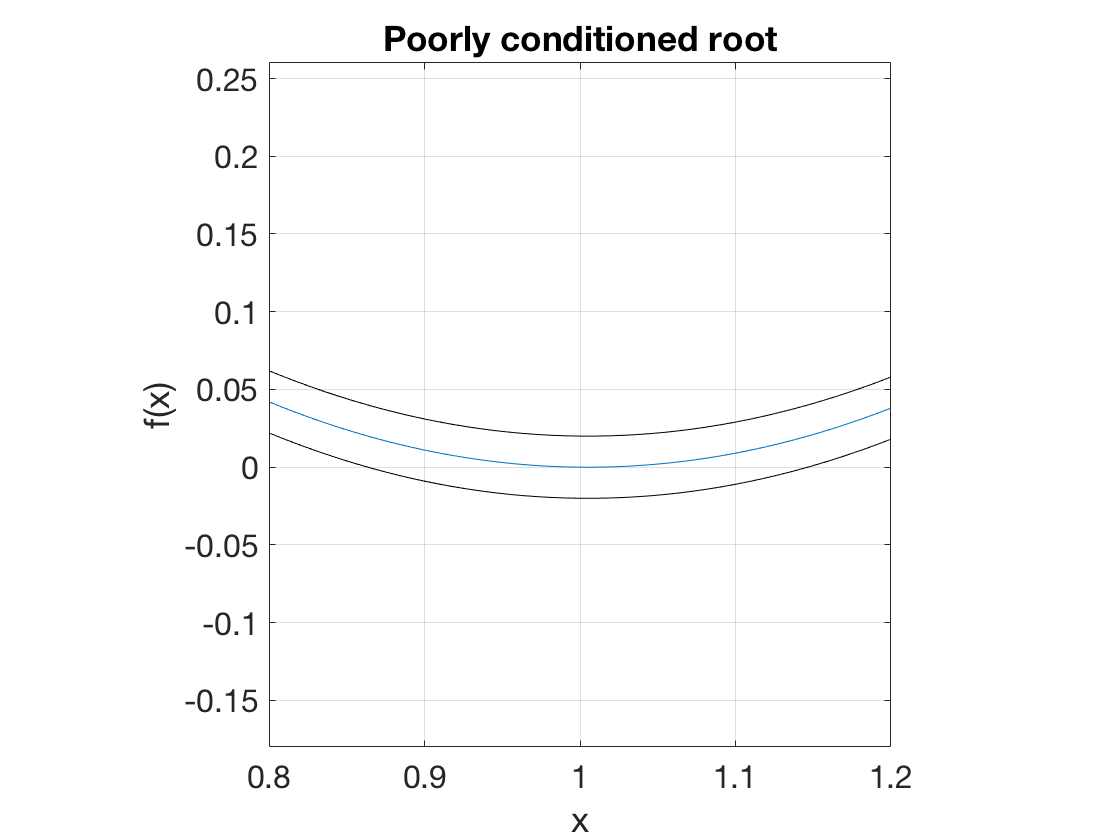

axis(axis), cla
fplot(f,interval)
fplot(@(x) f(x)+0.02,interval,'k')
fplot(@(x) f(x)-0.02,interval,'k')
title('Poorly conditioned root')    % ignore this line

The vertical displacements in this picture are exactly the same as before. But the potential *horizontal* displacement of the root is much wider. In fact, if we perturb the function upward by the amount drawn here, the root disappears entirely!